# Identificación del sistema: Respuesta al escalón.

Se realiza el ensayo al escalón, de subida y de bajada, y se importan los datos:

datos = readmatrix('datosV2.DAT');
t = datos(:,1) - 3.006216984;
output = datos(:,2) - min(datos(:,2));
input = datos(:,3)*(3/5);

Ts = mean(diff(t));

% Filtrado de los datos

% Datos de entrada:
% t
% input
% output

% Datos filtrados:
% Tt
% entrada
% salida

start_time = 0; 
end_time = 6;     
intervalo = 0.001; 

n = 1;  % MATLAB indexa desde 1
num_points = floor((end_time - start_time) / intervalo);

for i = 1:num_points
    % avanzar hasta que t(n) supere el límite del intervalo actual
    while (n < length(t)) && (t(n) < (i * intervalo + start_time))
        n = n + 1;
    end

    Tt(i) = (i - 1) * intervalo;
    entrada(i) = input(n);
    salida(i) = output(n);
end

entrada(1) = 0;
data_id = iddata(salida', entrada', intervalo);


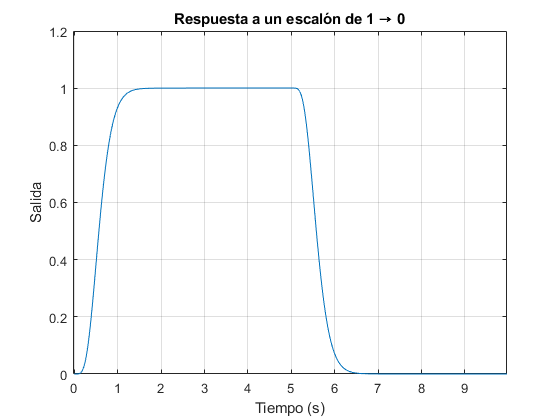


s = tf('s');

G_ideal = 1/(s*0.1 + 1)^6;

t = 0:0.01:10;           % tiempo de simulación
u = ones(size(t));       % empieza en 1
u(t > 5) = 0;            % a los 5 segundos baja a 0

[y, t_out] = lsim(tf2, u, t);
plot(t_out, y), grid on
xlabel('Tiempo (s)')
ylabel('Salida')
title('Respuesta a un escalón de 1 → 0')


L = 0.1

%plot(t, output);
%plot(data_id)